# Neural Networks Classification

## Introduction

The file `data5.mat` contains:

- $5000$ sample of handwritten digits in the matrix $X \in \mathcal M_{5000, 400}(\mathbb R)$ ($20\times20 px$ each);

- the associated $5000$ digit value in the column-vector $Y\in \mathcal M_{5000, 1}(\mathbb R)$ (we have identified the digit $0$ with the value $10$);

- the sample $\Theta \in \{\mathcal M_{401, 25}(\mathbb R), \mathcal M_{26, 10}(\mathbb R)\}$ set of some slightly trained weights for the neural network;

- the row-vector $s \in \mathcal M_{1, 3}(\mathbb N)$ with the number of units for each Layer.

Using the forward and the error backward propagation algorithm we will extimate the gradient of the cost function.

## Data Loading and Representation

In a general case we will load the two matrices $X \in \mathcal M_{m, n}(\mathbb R)$ and $Y \in \mathcal M_{m, 1}(\mathbb R)$ of respectivelly the Values and the evaluations of the training set.

In this particular case we have that the $i$-th row is a sample of the $Y[i]$ digit and the $n$ elements of each row of $X$ are the pixels of the handwritten digit scan (represented by a $20 \times 20$ matrix).

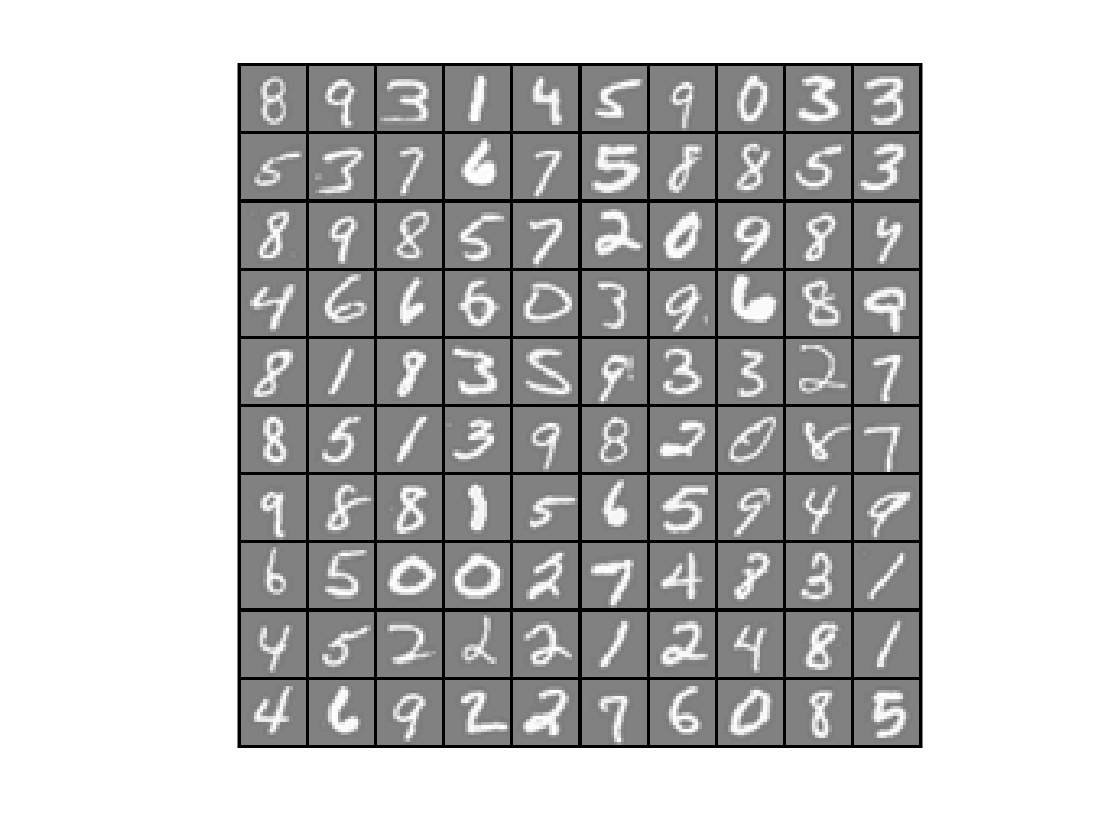

load('data5.mat', "X", "y");

[m, n] = size(X);
assert(isequal(size(y), [m, 1]));
classes = length(unique(y));

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

## Evaluation

### Neural Network Configuration

In order to build a Neural Network we have to decide a few parameters:

- the total number of Layers $L$ we will use in our neural network. Note that there will be $L - 2$ hidden layers.

- the number of units $s_l$ (without taking into account the bias) for each layer $l$.

Obs. Note that a standard choice of $L$ is 3 while a standard value for $s \in \mathcal M_{1, L}(\mathbb R)$ in any classification problem is:

    
$$s_l = \begin{cases} n & l = 1\\ k & 1 < l < L\\ \texttt{classes} & l = L \end{cases}$$


    where $k \in \mathbb N$ is some constant.

We should therefore choose randomly the values of the weights $\Theta$. Here $\Theta\{l\}(i,j) \to \Theta_{i,j}^{(l)}$ represents the weight between the $i$-th unit at layer $l$ and the $j$-th unit at layer $l+1$. In this example we have prepeared some slightly trained values in the file `data5.mat`.

load('data5.mat', "Theta", "s");
L = length(s);

### Cost Evaluation